# Sardinian varieties: how many clusters?

Acadèmia de su Sardu APS

18 September 2023

**Abstract: **Using the data published by Bolognesi (2007), we show that the varieties of the Sardinian lanuage can clearly be clustered into two macro-varieties, although the border between the two is not neat.

## Introduction

Let's first load and show the data that was published by Bolognesi (2007).

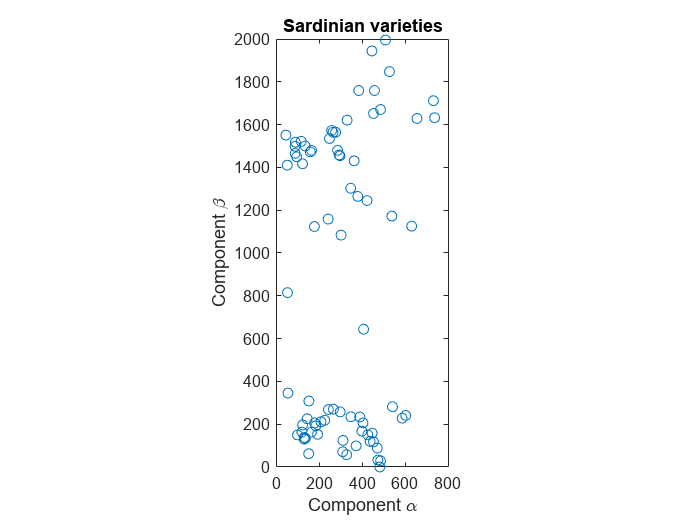

load('dialects.mat');
dialects = data(:, 1:2);
iPlotDialects(dialects);

First of all, we set the random number generator to ensure that the experiments are reproducible.

rng('default');

Several algorithms can be considered for clustering. We will consider three very popular algorithms:

- The **k-Means** algorithm (Lloyd, 1982) assigns points to the nearest cluster by distance, aiming to minimize the *variance* within each cluster. The variance is a statistical measurement of the "variation" of the data, because it measure how far the points are spread from their centre. It has a number of limitations (for example it expects the clusters to have a circular shape) but is a classical algorithm that is still often used in practice.

- The **linkage** algorithm looks at the distance between points in a cluster and the cluster's central point, which is called *centroid*. It is a *hierarchical *method, in the sense that is starts from small clusters and tries to combine them in a way that minimizes an overall measure of distance. The version used in this experiment is Ward's (1963). A hierarchical algorithm was also used by Bolognesi (2007).

- The **Gaussian mixture model** algorithm (McLachlan and D. Peel, 2000) looks at the distribution of the data and interprets it as a mixture of underlying components. It then tries to identify the characteristics of these components and uses them to construct the clusters. This algorithm can be considered a probabilistic and generalized version of the *k-Means* algorithm with fewer limitations.

And we will partition the data into up to 8 clusters

kValues = 1:8;

In this document, the description of the criteria is mainly taken from MATLAB's Statistics and Machine Learning Toolbox's documentation (The MathWorks, 2023).

## The Calinski-Harabasz criterion

The Calinski-Harabasz criterion (Calinski and Harabasz, 1974) is sometimes called the variance ratio criterion. Well-defined clusters have a large between-cluster variance and a small within-cluster variance. According to this rule, an index is associated with every clustering called "Calinski-Harabasz index", and the optimal number of clusters corresponds to the solution with the highest Calinski-Harabasz index value. 

criterion = 'CalinskiHarabasz';
criterionName = "Calinski-Harabasz";
yTrendLabel = "Calinski-Harabasz index (higher is better)";

### k-Means clustering

optimal = iEvaluateClustering(dialects, kValues, ...
    'kmeans', ...
    criterion, ...
    'k-Means', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



### Linkage clustering

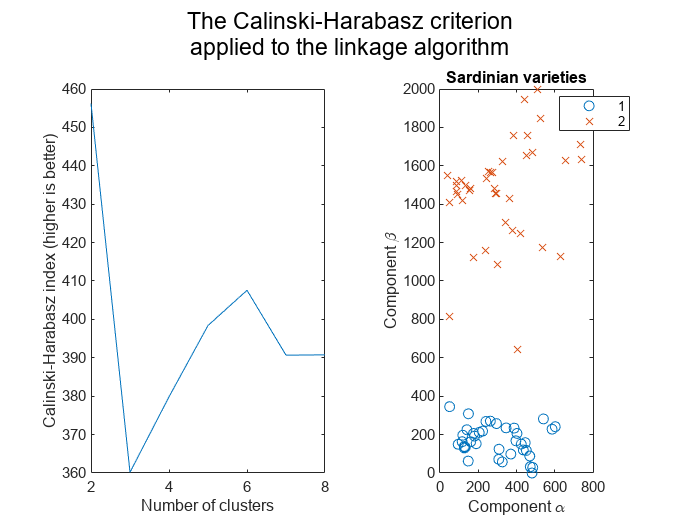

optimal = iEvaluateClustering(dialects, kValues, ...
    'linkage', ...
    criterion, ...
    'linkage', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



### Gaussian mixture model clustering

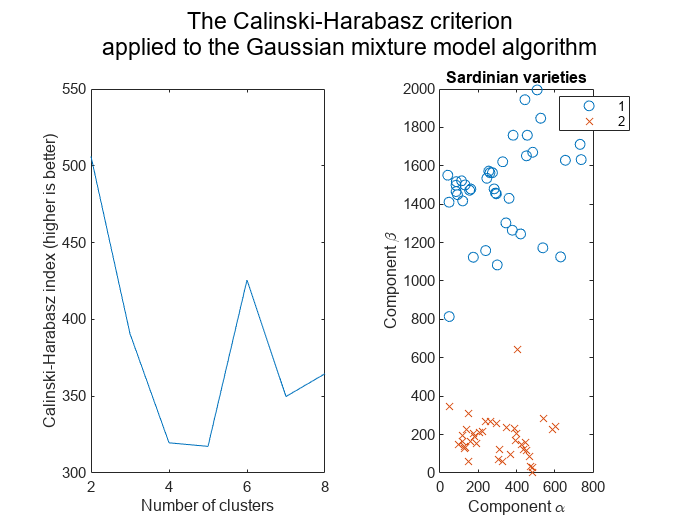

optimal = iEvaluateClustering(dialects, kValues, ...
    'gmdistribution', ...
    criterion, ...
    'Gaussian mixture model', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



## The Davies-Bouldin criterion

The Davies-Bouldin (Davies and Bouldin, 1979) is based on a ratio of within-cluster and between-cluster distances. This ratio is used to define a "Davies-Bouldin" index and the optimal clustering solution has the smallest Davies-Bouldin index value.

criterion = 'DaviesBouldin';
criterionName = "Davies-Bouldin";
yTrendLabel = "Dabies-Bouldin index (lower is better)";

### k-Means clustering

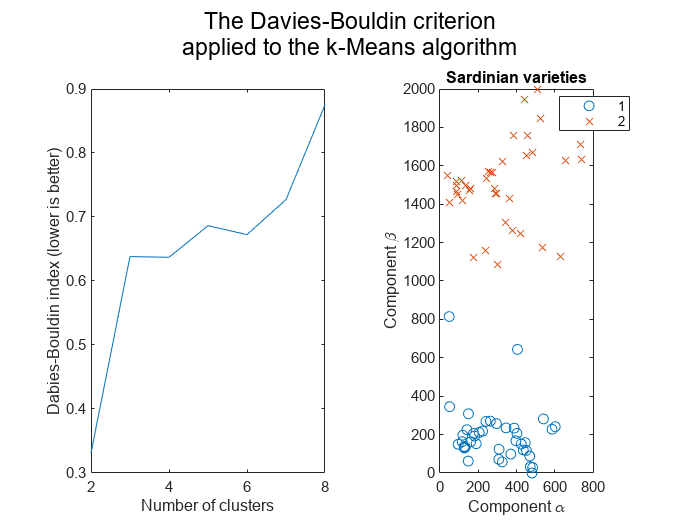

optimal = iEvaluateClustering(dialects, kValues, ...
    'kmeans', ...
    criterion, ...
    'k-Means', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



### Linkage clustering

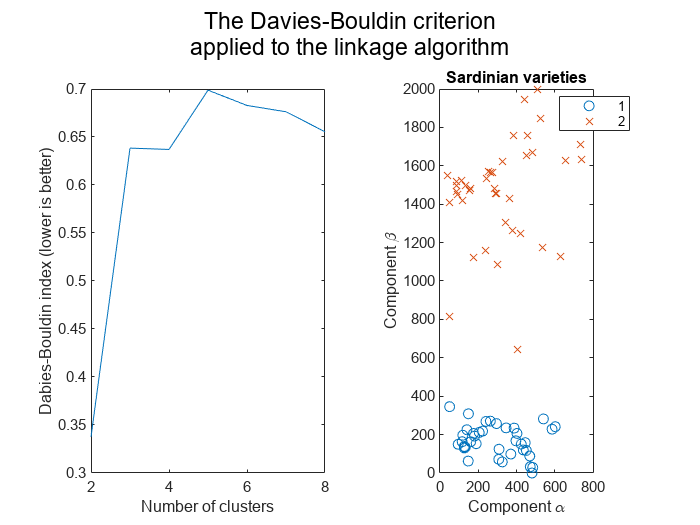

optimal = iEvaluateClustering(dialects, kValues, ....
    'linkage', criterion, ...
    "linkage", ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



### Gaussian mixture model clustering

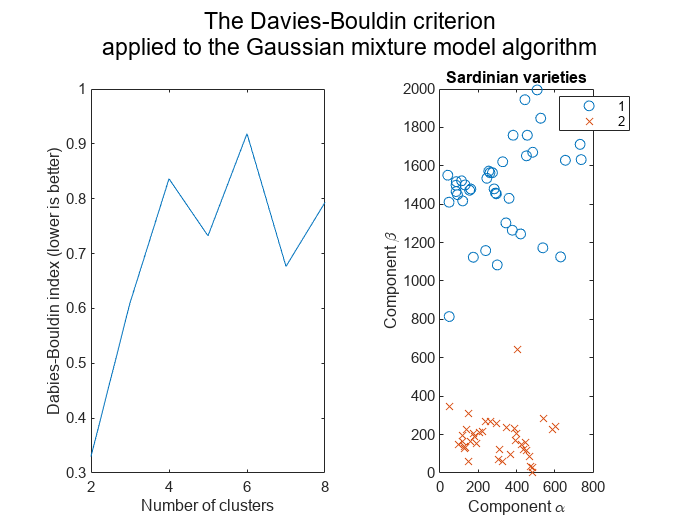

optimal = iEvaluateClustering(dialects, kValues, ...
    'gmdistribution', ...
    criterion, ...
    'Gaussian mixture model', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



## The gap criterion

The gap criterion (Tibshirani, Walther, and Hastie, 2001) looks at how the distribution of the clusters is spread and compares it to a reference distribution. This is used to define an index called "gap" and the optimal number of clusters corresponds to the solution with the largest local or global gap value within a tolerance range. 

criterion = 'gap';
criterionName = "gap";
yTrendLabel = "Gap value (higher is better)";

### k-Means clustering

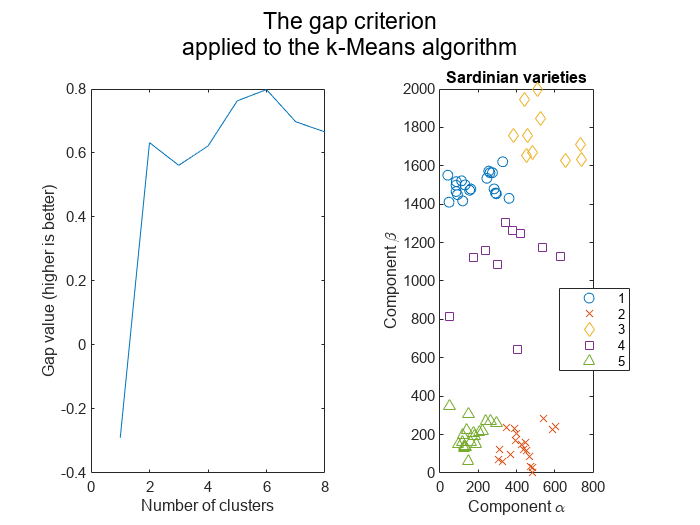

optimal = iEvaluateClustering(dialects, kValues, ...
    'kmeans', ...
    criterion, ...
    'k-Means', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     5



### Linkage clustering

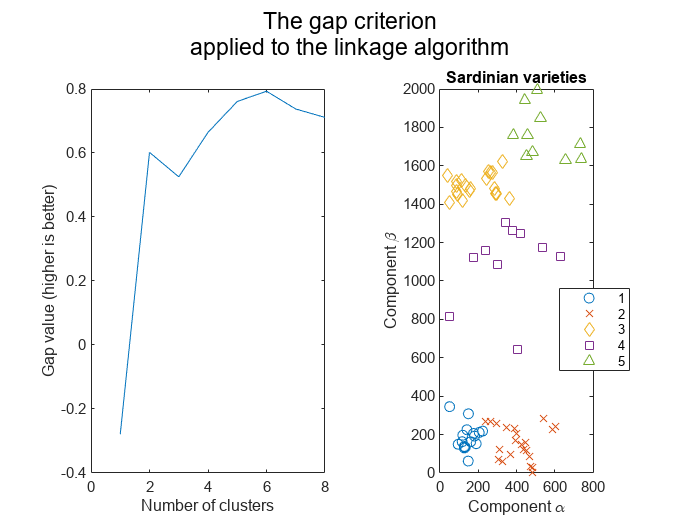

optimal = iEvaluateClustering(dialects, kValues, ....
    'linkage', ...
    criterion, ...
    "linkage", ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     5



### Gaussian mixture model clustering

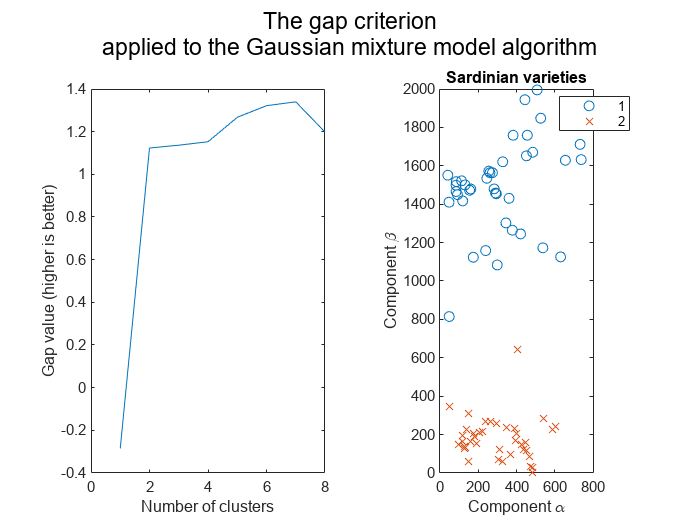

optimal = iEvaluateClustering(dialects, kValues, ...
    'gmdistribution', ...
    criterion, ...
    'Gaussian mixture model', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



## The silhouette criterion

The silhouette criterion (Rouseeuw, 1987) is based on an index called "silhouette value". The silhouette value for each point (observation in `X`) is a measure of how similar that point is to other points in the same cluster, compared to points in other clusters. If most points have a high silhouette value, then the clustering solution is appropriate. If many points have a low or negative silhouette value, then the clustering solution might have too many or too few clusters.

criterion = 'silhouette';
criterionName = "silhouette";
yTrendLabel = "Silhouette value (higher is better)";

### k-Means clustering

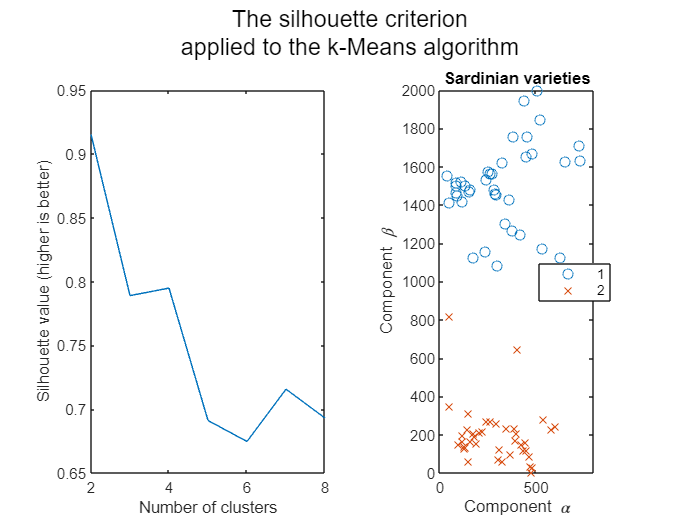

optimal = iEvaluateClustering(dialects, kValues, ...
    'kmeans', ...
    criterion, ...
    'k-Means', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



### Linkage clustering

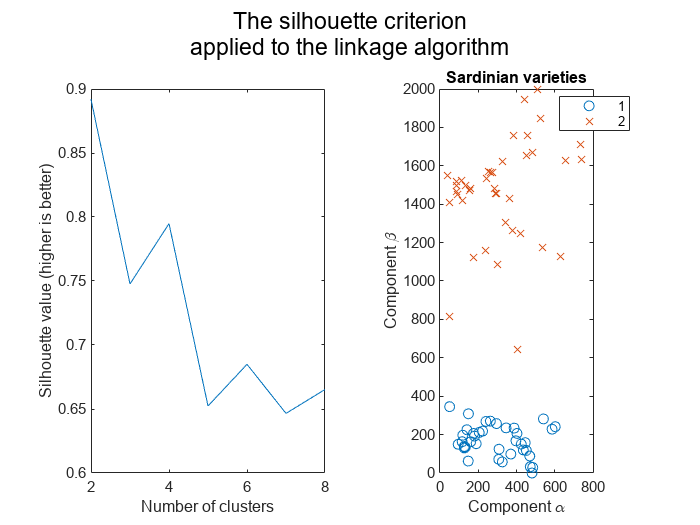

optimal = iEvaluateClustering(dialects, kValues, ...
    'linkage', ...
    criterion, ...
    "linkage", ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



### Gaussian mixture model clustering

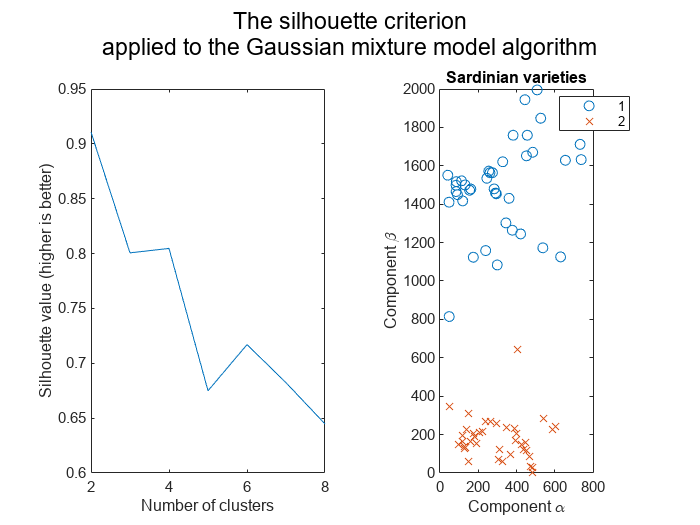

optimal = iEvaluateClustering(dialects, kValues, ...
    'gmdistribution', ...
    criterion, ...
    'Gaussian mixture model', ...
    criterionName, ...
    yTrendLabel);

The optimal number of clusters in this case is:

disp(optimal)

     2



## Discussion

Of the 12 combinations of clustering algorithms and evaluation criteria considered, 10 agreed that the optimal number of clusters is 2. Both of the results that disagreed were obtained with the gap criterion. Nonetheless, of the 10 combinations that agreed on the optimal number of clusters, one was obtained with the gap criterion. The other criteria evaluated the data based on:

- the distance between the points and the cluster's centroids,

- the variance of the data in each cluster,

- the silhouette value or "similarity" of the points within each cluster.

The way these indexes vary as the number of clusters increases does not depend much on the clustering algorithm. Under most criteria, the optimal number of clusters is quite consistently 2. Interestingly, this is the case for the "gap" criterion too, when one considers the Gaussian mixed model algorithm.

For the two combinations that did not give 2 as the number of optimal clusters, the gap value metric did not yield steep changes after 2 clusters. This suggests that the gap value does not change much after 2 clusters. Moreover, the suggested clustering does not contradict the 2-cluster partitioning, in the sense none of the clusters that were identified crossed the borders of the 2 clusters identified by the other 10 combinations: instead, the obtained clusters were partitions of the 2 optimal clusters identified in most experiments.

Also, considering the plots where 2 was the number of optimal clusters, one can note that the points in the border are not consistently identified as belonging to one specific cluster. Nonetheless, the Gaussian mixture model algorithm does assign a point to more than one category, which is why the gap metric also gives 2 optimal clusters with this algorithm.

## Conclusions

In terms of distance between points and cluster centroids, variance of data, and similarity between points within each cluster, the results show that 2 is the optimal value for the number of clusters. The gap value metric instead promotes smaller clusters that are in practice partitions of the 2 optimal clusters identified with the other metrics. The association of points with clusters is not consistent in the middle region, which corresponds to dialects of the transitional or *mesania *area, but this not an issue a point can be associated with more than one cluster.

## Bibliography

Bolognesi (2007)* “La limba sarda comuna e le varietà tradizionali del sardo”*, Retrieved on 18 September 2023 from [http://www.sardegnacultura.it/documenti/7_88_20070518130841.pdf.](http://www.sardegnacultura.it/documenti/7_88_20070518130841.pdf.)

Calinski and Harabasz (1974) *“A dendrite method for cluster analysis”*, *Communications in Statistics,* Vol. 3, No. 1, pp. 1–27.

Davies and Bouldin (1979) *“A Cluster Separation Measure”,* *IEEE Transactions on Pattern Analysis and Machine Intelligence,* Vol. PAMI-1, No. 2, pp. 224–227.

Lloyd (1982) *“Least Squares Quantization in PCM”,* *IEEE Transactions on Information Theory,* Vol. 28, pp. 129–137.

McLachlan and D. Peel (2000) *"Finite Mixture Models*", Hoboken, NJ: John Wiley & Sons, Inc., 2000.

Rouseeuw (1987) *“Silhouettes: a graphical aid to the interpretation and validation of cluster analysis”,* *Journal of Computational and Applied Mathematics,* Vol. 20, No. 1, pp. 53–65.

The MathWorks (2023) "Statistics and Machine Learning Toolbox: User's Guide (R2023b)". Retrieved on 18 September 2023 from [https://uk.mathworks.com/help/pdf_doc/stats/stats.pdf.](https://uk.mathworks.com/help/pdf_doc/stats/stats.pdf.)

Tibshirani, Walther, and Hastie (2001) *“Estimating the number of clusters in a data set via the gap statistic”,* *Journal of the Royal Statistical Society: Series B, *Vol. 63, Part 2, pp. 411–423.

Ward (1963) *"Hierarchical Grouping to Optimize an Objective Function", Journal of the American Statistical Association, *Vol. 58, pp. 236-244.

## Helper functions

function optimal = iEvaluateClustering(dialects, kValues, ...
    algorithm, ...
    criterion, ...
    algorithmName, ...
    criterionName, ...
    yTrendLabel)
criterionEvaluation = evalclusters(dialects, algorithm, ...
    criterion, ...
    KList=kValues);
figure()

% Show how clustering was chosen
subplot(1, 2, 1);
plot(criterionEvaluation.CriterionValues);
xlabel("Number of clusters");
ylabel(yTrendLabel);

% Show the clustering
subplot(1, 2, 2);
iPlotDialects(dialects, criterionEvaluation.OptimalY);

sgtitle(compose(...
    'The %s criterion\napplied to the %s algorithm', ...
    criterionName, algorithmName));
optimal = criterionEvaluation.OptimalK;
end


function iPlotDialects(data, categories)
if nargin==1
    categories = ones(size(data, 1), 1);
end

yData = max(data(:, 2)) - data(:, 2);
gscatter(data(:,1), yData, categories, ...
    [], ... % Marker color
    "oxds^*");
alpha(0.8);
daspect([1, 1, 1]);

title('Sardinian varieties')
xlabel("Component \alpha");
ylabel("Component \beta");
if nargin==1
    legend('off');
end
end